clc
clear all
format long g
% Template for assignment 1, advanced part
% ----------------------------------------------
% INPUTS
% ------

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%55
NELEM = 60 ;  % Number of elements
nsteps = 61 ;  % Number of steps
stepsPOST = [1:12:nsteps]; % Steps to post-process


A0 = 1e-2; %m  % Reference AREA
E0 = 10 ; % MPa  % Reference Young's Modulus
sigma_0 = 1; %MPa  % Saturation stress
L = 1 ;%m    % Length of the beam
T = 1; % s Final time
um = 0.2*L; %m   % Maximum displacement
AreaFUN = @(x) (A0*(1+2*(x/L).*(x/L-1)))  ;  % Area as a function of the distance from the left end
stressFUN = @(strain) (sigma_0*(1-exp(-E0/sigma_0*strain))) ;  % Constitutive equation (stress versus strain)
DerStressFUN = @(strain) (E0*exp(-E0/sigma_0*strain)) ;  % Tangent modulus (Derivative of the stress with respect to the strain)
r = [1,NELEM+1]  ; % Indexes Prescribed DOF  %
uEND = @(t) (t/T*um);  %  Non-zero prescribed displacement, as a function of time
TOL_residual = 1e-6;  % Convergence tolerance for the Newton-Raphson
MAXITER = 50 ;  % Maximum number of iterations  for the Newton-Raphson
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% END INPUTS % ------------------------------------------
% MESH INFORMATION
nnode = NELEM+1 ;
COOR = linspace(0,L,nnode)' ;
CN = [(1:(nnode-1))',(2:nnode)'] ;
l = setdiff([1:nnode],r) ;

d = zeros(nnode,1) ;  % Displacement at time tn

TIMES = linspace(0,T,nsteps) ;

% STORE INFORMATION for post-processing purpose
% -----------------------
STRESS_GLO = zeros(NELEM,nsteps) ;
STRAIN_GLO  = zeros(NELEM,nsteps) ;
d_GLO  = zeros(nnode,length(stepsPOST)) ;

iplot = 1;



for istep=1:nsteps
    t = TIMES(istep) ;  % Time
    d(nnode) = uEND(t) ;    
    
    disp(['Number of  step = ',num2str(istep), ', Time = ',num2str(t),', uEND =  ',num2str( uEND(t)) ])
    disp('********************************************************************')
    % Boundary conditions
    %-------------------
    % Compute the vector of internal forces = residual
    % as a function of the nodal displacement n
    
    % Solution of the equations Residual(d) = 0     via Newton-Raphson
    % algoritm
    d_k = d; %   nodal displacements at iteration k
    k = 0 ; % Number of iteration
    while  k <= MAXITER
        % ASsembly the residual vector (= internal forces)
        [Residual,STRAIN,STRESS] = AssemblyFint(COOR,CN,d_k,stressFUN,AreaFUN) ;
        normRESIDUAL = norm(Residual(l)) ; % Euclidean norm residual
        disp(['k = ',num2str(k),' res=',num2str(normRESIDUAL),', MAX strain = ',num2str(max(STRAIN)),', MAX stress = ',num2str(max(STRESS))])
        if normRESIDUAL < TOL_residual
            % Convergence
            d = d_k ;
            break
        end
        % The norm of the residual is greater than the prescribed
        % tolerance.  This means that equilibrium is not met
        % Let us calculate the new displacement vector
        
        % Compute the Jacobian of the system of equations
        K = AssemblyKnon(COOR,CN,d_k,AreaFUN,DerStressFUN);
            Delta_d_l = -K(l,l)\Residual(l) ;
        d_k(l) = d_k(l) + Delta_d_l;
        k = k +1 ;
    end
    
    if  k >  MAXITER
        error('The Newtown-R. algorithm has failed to converge')
    else
        d=d_k ;
        d_GLO(:,iplot) = d ;
        STRAIN_GLO(:,iplot) = STRAIN ;
        STRESS_GLO(:,iplot) = STRESS ;
        iplot = iplot +1 ;
    end
end

Number of  step = 1, Time = 0, uEND =  0


********************************************************************


k = 0 res=0, MAX strain = 0, MAX stress = 0


Number of  step = 2, Time = 0.1, uEND =  0.02


********************************************************************


k = 0 res=0.0078252, MAX strain = 0.2, MAX stress = 0.86466
k = 1 res=0.067158, MAX strain = 0.055528, MAX stress = 0.42609
k = 2 res=0.022733, MAX strain = 0.045056, MAX stress = 0.36273
k = 3 res=0.0066062, MAX strain = 0.033993, MAX stress = 0.28818
k = 4 res=0.001233, MAX strain = 0.027683, MAX stress = 0.24182
k = 5 res=7.1023e-05, MAX strain = 0.025896, MAX stress = 0.22814
k = 6 res=2.735e-07, MAX strain = 0.02578, MAX stress = 0.22725


Number of  step = 3, Time = 0.2, uEND =  0.04


********************************************************************


k = 0 res=0.0068329, MAX strain = 0.21356, MAX stress = 0.88182
k = 1 res=0.066455, MAX strain = 0.085352, MAX stress = 0.57408
k = 2 res=0.022694, MAX strain = 0.074849, MAX stress = 0.52692
k = 3 res=0.0067761, MAX strain = 0.062667, MAX stress = 0.46563
k = 4 res=0.0013673, MAX strain = 0.055438, MAX stress = 0.42557
k = 5 res=9.6266e-05, MAX strain = 0.053137, MAX stress = 0.4122
k = 6 res=5.7326e-07, MAX strain = 0.052951, MAX stress = 0.41111


Number of  step = 4, Time = 0.3, uEND =  0.06


********************************************************************


k = 0 res=0.00603, MAX strain = 0.22605, MAX stress = 0.8957
k = 1 res=0.06774, MAX strain = 0.11767, MAX stress = 0.69169
k = 2 res=0.023342, MAX strain = 0.10726, MAX stress = 0.65789
k = 3 res=0.0071628, MAX strain = 0.093626, MAX stress = 0.60791
k = 4 res=0.0015645, MAX strain = 0.085221, MAX stress = 0.57353
k = 5 res=0.00013557, MAX strain = 0.082199, MAX stress = 0.56045
k = 6 res=1.2788e-06, MAX strain = 0.081889, MAX stress = 0.55908
k = 7 res=1.1653e-10, MAX strain = 0.081886, MAX stress = 0.55907


Number of  step = 5, Time = 0.4, uEND =  0.08


********************************************************************


k = 0 res=0.005384, MAX strain = 0.23739, MAX stress = 0.90688
k = 1 res=0.071307, MAX strain = 0.15321, MAX stress = 0.78392
k = 2 res=0.024792, MAX strain = 0.14316, MAX stress = 0.76108
k = 3 res=0.0078146, MAX strain = 0.12759, MAX stress = 0.72081
k = 4 res=0.0018455, MAX strain = 0.11767, MAX stress = 0.69171
k = 5 res=0.00019704, MAX strain = 0.11363, MAX stress = 0.67899
k = 6 res=2.9843e-06, MAX strain = 0.1131, MAX stress = 0.67728
k = 7 res=7.1164e-10, MAX strain = 0.11309, MAX stress = 0.67725


Number of  step = 6, Time = 0.5, uEND =  0.1


********************************************************************


k = 0 res=0.004868, MAX strain = 0.24747, MAX stress = 0.91581
k = 1 res=0.077567, MAX strain = 0.193, MAX stress = 0.85485
k = 2 res=0.027201, MAX strain = 0.18376, MAX stress = 0.84081
k = 3 res=0.0087942, MAX strain = 0.16555, MAX stress = 0.80901
k = 4 res=0.0022363, MAX strain = 0.15367, MAX stress = 0.78491
k = 5 res=0.0002921, MAX strain = 0.14819, MAX stress = 0.77279
k = 6 res=7.0851e-06, MAX strain = 0.14726, MAX stress = 0.77067
k = 7 res=4.438e-09, MAX strain = 0.14724, MAX stress = 0.77062


Number of  step = 7, Time = 0.6, uEND =  0.12


********************************************************************


k = 0 res=0.0044603, MAX strain = 0.25621, MAX stress = 0.92286
k = 1 res=0.087229, MAX strain = 0.23846, MAX stress = 0.90787
k = 2 res=0.030835, MAX strain = 0.23087, MAX stress = 0.90061
k = 3 res=0.010203, MAX strain = 0.20898, MAX stress = 0.87629
k = 4 res=0.002776, MAX strain = 0.19449, MAX stress = 0.857
k = 5 res=0.00043739, MAX strain = 0.18698, MAX stress = 0.84584
k = 6 res=1.6686e-05, MAX strain = 0.18535, MAX stress = 0.84331
k = 7 res=2.6829e-08, MAX strain = 0.18528, MAX stress = 0.84321


Number of  step = 8, Time = 0.7, uEND =  0.14


********************************************************************


k = 0 res=0.0041433, MAX strain = 0.26359, MAX stress = 0.92834
k = 1 res=0.10128, MAX strain = 0.29166, MAX stress = 0.94588
k = 2 res=0.036062, MAX strain = 0.28708, MAX stress = 0.94335
k = 3 res=0.012178, MAX strain = 0.26001, MAX stress = 0.92573
k = 4 res=0.0035168, MAX strain = 0.24198, MAX stress = 0.91106
k = 5 res=0.00065505, MAX strain = 0.23158, MAX stress = 0.90131
k = 6 res=3.7984e-05, MAX strain = 0.22875, MAX stress = 0.89848
k = 7 res=1.4892e-07, MAX strain = 0.22856, MAX stress = 0.89829


Number of  step = 9, Time = 0.8, uEND =  0.16


********************************************************************


k = 0 res=0.0039028, MAX strain = 0.26956, MAX stress = 0.9325
k = 1 res=0.12106, MAX strain = 0.35555, MAX stress = 0.97143
k = 2 res=0.043376, MAX strain = 0.35579, MAX stress = 0.9715
k = 3 res=0.014905, MAX strain = 0.32168, MAX stress = 0.95992
k = 4 res=0.0045269, MAX strain = 0.29875, MAX stress = 0.94959
k = 5 res=0.000973, MAX strain = 0.28428, MAX stress = 0.94174
k = 6 res=8.1759e-05, MAX strain = 0.27942, MAX stress = 0.93883
k = 7 res=7.2358e-07, MAX strain = 0.27894, MAX stress = 0.93854


Number of  step = 10, Time = 0.9, uEND =  0.18


********************************************************************


k = 0 res=0.0037269, MAX strain = 0.27894, MAX stress = 0.93854
k = 1 res=0.14812, MAX strain = 0.43407, MAX stress = 0.98697
k = 2 res=0.053357, MAX strain = 0.43965, MAX stress = 0.98768
k = 3 res=0.018597, MAX strain = 0.39747, MAX stress = 0.98122
k = 4 res=0.0058857, MAX strain = 0.36802, MAX stress = 0.97478
k = 5 res=0.0014225, MAX strain = 0.34803, MAX stress = 0.9692
k = 6 res=0.00016352, MAX strain = 0.33992, MAX stress = 0.9666
k = 7 res=2.9573e-06, MAX strain = 0.33876, MAX stress = 0.96621
k = 8 res=1.0141e-09, MAX strain = 0.33874, MAX stress = 0.9662


Number of  step = 11, Time = 1, uEND =  0.2


********************************************************************


k = 0 res=0.0036062, MAX strain = 0.33874, MAX stress = 0.9662
k = 1 res=0.18402, MAX strain = 0.531, MAX stress = 0.99506
k = 2 res=0.066585, MAX strain = 0.53666, MAX stress = 0.99533
k = 3 res=0.02347, MAX strain = 0.48841, MAX stress = 0.99243
k = 4 res=0.0076725, MAX strain = 0.45201, MAX stress = 0.98911
k = 5 res=0.0020334, MAX strain = 0.42546, MAX stress = 0.9858
k = 6 res=0.00030087, MAX strain = 0.4127, MAX stress = 0.98387
k = 7 res=9.9206e-06, MAX strain = 0.41017, MAX stress = 0.98345
k = 8 res=1.1773e-08, MAX strain = 0.41008, MAX stress = 0.98344


**PLOTS**

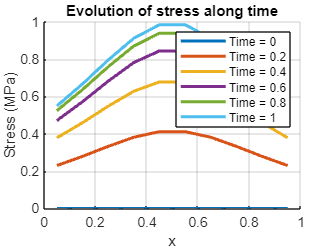

% Evolution of stresses along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Stress (MPa)')
title('Evolution of stress along time')
COOR_gauss = (COOR(CN(:,2))+  COOR(CN(:,1)))/2 ;
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR_gauss,STRESS_GLO(:,stepsPOST(i)),'LineWidth',2) ;
    %LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i)))] ;end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

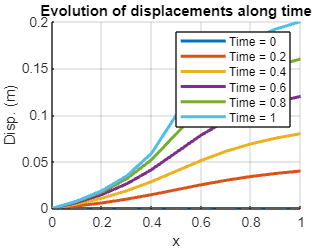


% Evolution of displacements along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Disp. (m)')
title('Evolution of displacements along time')
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR,d_GLO(:,stepsPOST(i)),'LineWidth',2) ;
   %LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i)))] ;

end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

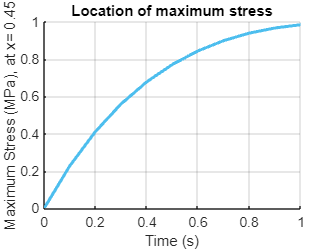




% Location of maximum stress

[stressEND,indELEM ]= max(STRESS_GLO(:,end)) ;
COOR_max_stress= COOR_gauss(indELEM) ;

figure
hold on
title('Location of maximum stress')
xlabel('Time (s)')
ylabel([['Maximum Stress (MPa), at x= ',num2str(COOR_max_stress)]]) ;
for i = 1:nsteps_plot
    h =   plot(TIMES,STRESS_GLO(indELEM,:),'LineWidth',2) ;
end
grid on

%legend(h,['NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)])

%legend('off')
%legend
